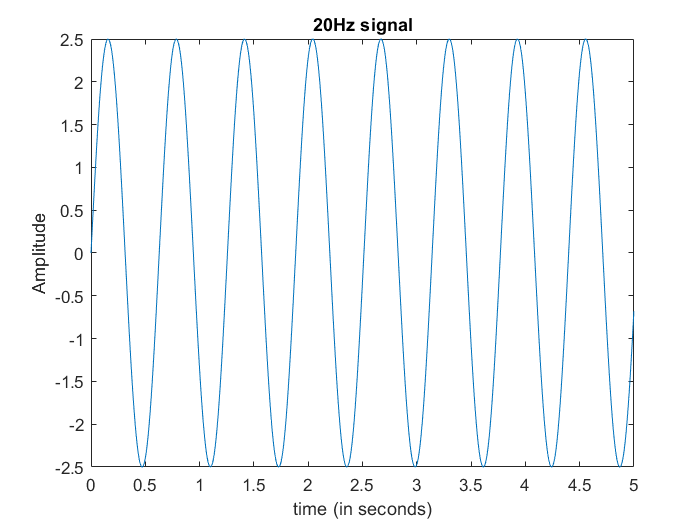

   clc;
   clear;
   
   Fs = 1000;                   % samples per second
   dt = 1/Fs;                   % seconds per sample
   StopTime = 5;             % seconds
   t = (0:dt:StopTime-dt);     % seconds
   %%Sine wave:
   Fc = 10;                     % hertz
   x = 2.5*sin(Fc*t);
   % Plot the signal versus time:
   figure;
   plot(t,x);
   xlabel('time (in seconds)'); ylabel('Amplitude')
   title('20Hz signal');

   
   N = size(t,2);

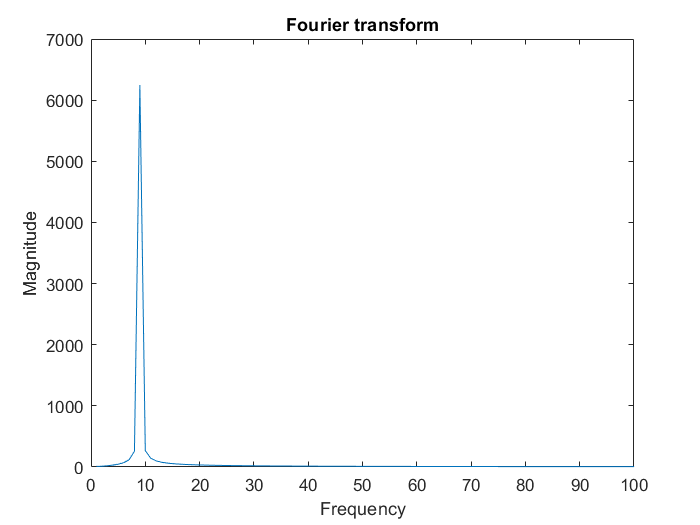

detrended_AZ = fft(x);
plot(abs(detrended_AZ));
xlabel('Frequency'); ylabel('Magnitude'); title('Fourier transform')
xlim([0 100])


maxSpec = max(abs(detrended_AZ))

maxSpec = 6.2475e+03


y = abs(detrended_AZ);
f  = 0:N-1;

%find where in the array the significant freqeuncy occurs
[f_sig,] = find(y==maxSpec) 

f_sig =            9        4993



%find the first spectral component of the maximum
f_sig = min(f_sig)

f_sig = 9

%detrended_AZ = abs(fft(x));
%x = detrend(x);

size(detrended_AZ,2)

ans = 5000

f1 = 5

f1 = 5

f2 = 25

f2 = 25

f  = 0:size(abs(detrended_AZ),2)-1;
fc = 1/(2.*dt);


filtered_data = zeros(size(N));
L = 2*f_sig

L = 18


for i = 1:size(f,2)
    if f(i)<L
        fil = tukeywin(L,1.5);
        filtered_data(i) = fil(i).*detrended_AZ(i);
    else
        %fc_above = -1./(2*pi.*(f.^2));
        %filtered_data(i) = fc_above(i).*detrended_AZ(i);
        filtered_data(i) = 0;
    end
end

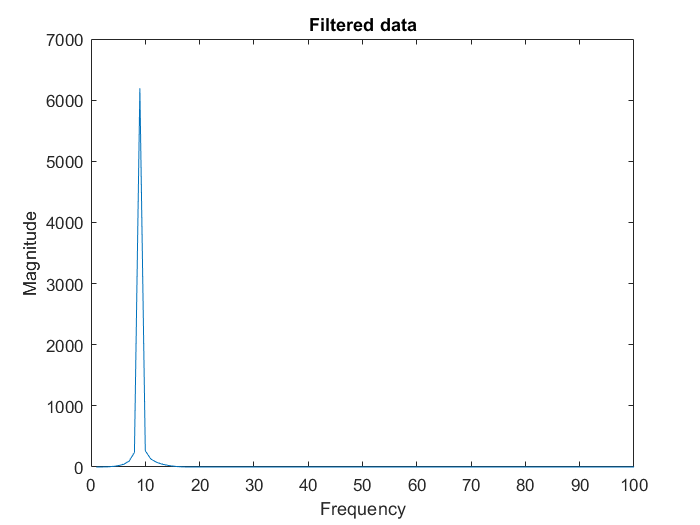

plot(abs(filtered_data))
xlim([0 100])
xlabel('Frequency'); ylabel('Magnitude'); title('Filtered data')


w = 2*pi.*Fc

w = 62.8319

z = (-1./(w.^2)).*abs(filtered_data); 

%z_time = ifft(abs(z))

PSD = 2.*(abs(z)).^2;

delta_f = f(2)-f(1);
% m0=0
% for j = 1:size(z,2)
%     m0 = m0 + PSD(j);
% end

m0 = sum(PSD)

m0 = 4.9451

m0 = delta_f*m0

m0 = 4.9451


hs = sqrt(m0)

hs = 2.2238

Hs = 0.1*hs + hs

Hs = 2.4461